clear
close all
clc

%% ROBOT ARM - DH PARAMETERE

L1 = 10; % base høyde
L2 = 70; % Over arm
L3 = 60; % under arm
L4 = 20; % håndledd1 
L5 = 20; % håndledd2 
L6 = 15; % siste lenke

L(1) = Link('revolute', 'd', L1, 'a', 0, 'alpha', pi/2, 'offset', 0);
L(2) = Link('revolute', 'd', 0, 'a', L2, 'alpha', 0, 'offset', pi/2);
L(3) = Link('revolute', 'd', 0, 'a', L3, 'alpha', 0, 'offset', 0);
L(4) = Link('revolute', 'd', L4, 'a', 0, 'alpha', -pi/2, 'offset', -pi/2);
L(5) = Link('revolute', 'd', L5, 'a', 0, 'alpha', pi/2, 'offset', 0);
L(6) = Link('revolute', 'd', L6, 'a', 0, 'alpha', 0, 'offset', 0);

six_link = SerialLink(L, 'name', 'Palletizing Robot');

%% ROBOT VISUALISERING

q = zeros(1,6);

six_link.plot(q, ...
    'workspace', [-250 250 -200 200 0 350], ...
    'scale', 1, ...
    'jointdiam', 1, ...
    'jointlen', 1, ...
    'noshadow');

hold on
axis equal
grid on
view([106 25])

%% ------------ Visuelle objekter ------------ %%
%palletPos  = [0 -60 7.2];
%conveyorPos(mid)  = [-135 0 15];
%boxPos  = [-100 0 30];
%cameraPos = [-150 150 200];

%% Pallen
drawBox([0 -80 7.2], ...
        [120 80 14.4], ...
        [0.65 0.40 0.20]);

%% Transportbåndet (overflate 20 cm over bakken)
drawBox([-135 0 15], ...
        [160 60 10], ...
        [0.25 0.25 0.25]);

%% Boks (1 m i negativ X-retning)
drawBox([-100 0 30], ...
        [40 40 20], ...
        [0.85 0.55 0.20]);


%% KAMERA
cameraPos = [-150 150 200];
T_WC = transl(cameraPos) * trotx(120, 'deg'); %% 120 grader rotasjon rondt x aksen
trplot(T_WC, 'frame', 'C', 'length', 30);
drawBox(cameraPos, ...
        [12 12 8], ...
        [0.1 0.3 0.8]);

%% Forward kinematics
T = six_link.fkine(q)

 

T = 
         1         0         0         0
         0         0        -1       -35
         0         1         0       160
         0         0         0         1


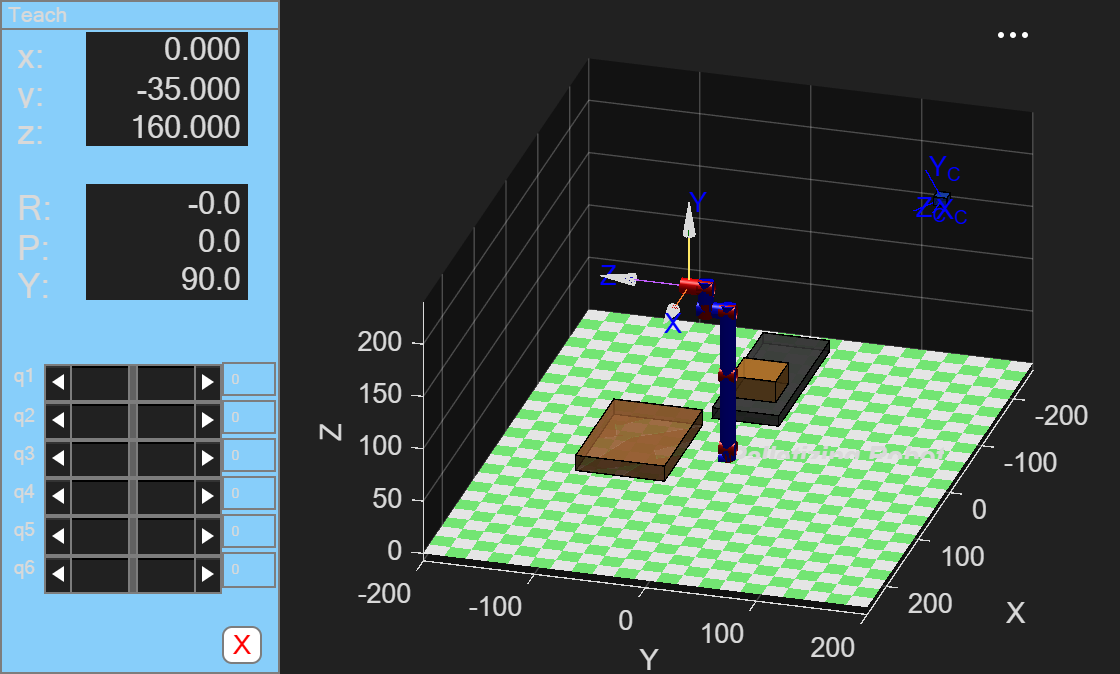


%% Visualisere med teach
six_link.teach(q);



%% Hjelpefunksjon som tegner boks (laget av ChatGPT)
function drawBox(center, dims, color)

    x = center(1);
    y = center(2);
    z = center(3);

    lx = dims(1)/2;
    ly = dims(2)/2;
    lz = dims(3)/2;

    V = [
        x-lx y-ly z-lz;
        x+lx y-ly z-lz;
        x+lx y+ly z-lz;
        x-lx y+ly z-lz;
        x-lx y-ly z+lz;
        x+lx y-ly z+lz;
        x+lx y+ly z+lz;
        x-lx y+ly z+lz
    ];

    F = [
        1 2 3 4;
        5 6 7 8;
        1 2 6 5;
        2 3 7 6;
        3 4 8 7;
        4 1 5 8
    ];

    patch('Vertices', V, ...
          'Faces', F, ...
          'FaceColor', color, ...
          'FaceAlpha', 0.8, ...
          'EdgeColor', 'k');
end


Rekkevidde i XY-planet: 35.00 cm
